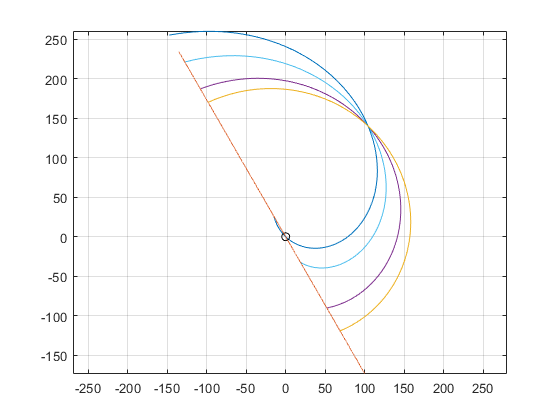

a = 200;
b = 300;
s = 200;
m = a/b;

rMin = 0.5 * (pi/4) * (a + s);
rMax = 0.5 * (pi/4) * (b + s);

thetaMin = 0;
thetaMax = deg2rad(120);


x = -135:0.01:100;

%Initial orientation of shell
initialAxis = tan(thetaMax)*x;

c2 = (rMax - rMin)/thetaMax;
c1 = rMin;

theta = -deg2rad(60):0.01*pi:thetaMax;
y = c1 + c2.*theta;

plot(0, 0, 'k-o'); hold on;
plot(x, initialAxis); hold on;
plot(y.*cos(theta), y.*sin(theta)); hold on;

axis equal
grid on